# Radar Signal Processing - Attacks

Creating this script to study the effect of different attacks on the radar signal processing

## Initialize the simulator

clear;
simulator = Simulator_revA();
%setup the victim's chirp parameters

%simulator.load_B210_victim_params;
%simulator.load_B210_attacker_params;

simulator.load_realistic_victim_params;
simulator.load_realisitc_attacker_params;

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.42 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 42.12 us
	 Chirp Tx Bandwidth: 		 453.21 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.07 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 6.41 ms


simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.44 m/s
	 Velocity Resolution 		 0.30 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 458.88 MHz
	 Downsampling factor 		 64
	 Sweep time 			 42.12 us
	 Samples per chirp 		 22976.00 


## Initialize the Target Emulator

target_range = 70; %m
target_velocity = 7; % m/s
emulated_target = FMCW_Emulator_revA(simulator.Victim,target_range,target_velocity,"target");

## Initialize an emulated Attacker

attack_range = 50; %m
attack_velocity = 1; % m/s
 emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"target");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"velocity spoof - similar velocity");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"velocity spoof - noisy");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,"range spoof - similar slope");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,...
%     "range spoof - similar slope,velocity spoof - noisy");
% emulated_attacker = FMCW_Emulator_revA(simulator.Victim,attack_range,attack_velocity,...
%     "range spoof - similar slope,velocity spoof - similar velocity");

Writing code to simulate the signal propogation through the signal processing chain

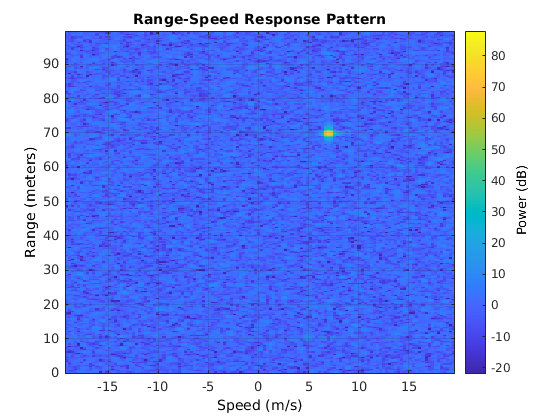

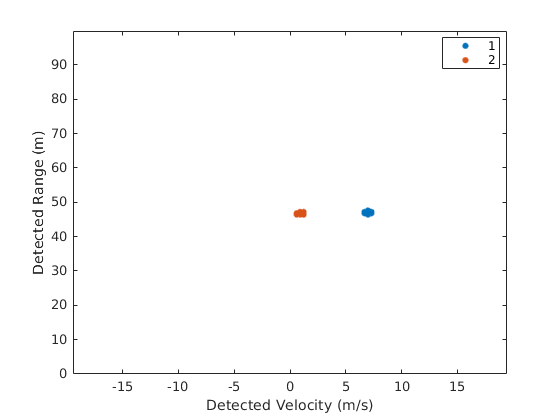

%specify the number of frames and chirps to compute
frames_to_compute = 100;
chirps_to_compute = simulator.Victim.NumChirps;

%get the radar chirp generator and the target emulator ready
emulated_target.reset_emulated_chirp_computation();
emulated_attacker.reset_emulated_chirp_computation();
simulator.Victim.precompute_radar_chirps();


%configure things to be able to generate a movie
figure
axis fill
F_rngdop(frames_to_compute) = struct('cdata',[],'colormap',[]);
F_clusters(frames_to_compute) = struct('cdata',[],'colormap',[]);

%configure to save each frame of the range doppler for further processing
rng_dopp_responses = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps,frames_to_compute);


for frame = int32(1:frames_to_compute)
    
    %compute the emulated chirps for the current frame
    emulated_target.compute_next_emulated_chirps();

    %compute the emulated attack chirps for the current frame
    emulated_attacker.compute_next_emulated_chirps();

    %initialize a clean radar cube
    radar_cube = zeros(simulator.Victim.ADC_Samples,simulator.Victim.NumChirps);
    
    for chirp = int32(1:chirps_to_compute)
    
        %get the Tx chirp and the chirp received from the emulator
        if  frame < 15
            Rx_sig = emulated_target.emulated_chirps(:,chirp);
        else
            Rx_sig = 4 * emulated_attacker.emulated_chirps(:,chirp) + emulated_target.emulated_chirps(:,chirp);
        end
        Rx_sig = awgn(Rx_sig,20);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
        
        %dechirp and downsample the signal
        sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.FMCW_dechirp_and_decimate(Tx_sig,Rx_sig);
        
        %assemble the radar cube
        radar_cube(:,chirp) = sampled_IF_sig;
    end
    
    %range-doppler response
    [resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);

    %save the range_doppler response
    rng_dopp_responses(:,:,frame) = resp;

    %plot the doppler response and save it for a movie
    plotResponse(simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse,radar_cube);
    drawnow
    F_rngdop(frame) = getframe(gcf);
    
    %CA CFAR 2-D
    detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
    detected_velocities = dopgrid(detections(2,:));
    detected_ranges = rnggrid(detections(1,:));
    
    %DBSCAN Clustering
    if ~isempty(detections)
        idx = dbscan(detections.',simulator.Victim.Radar_Signal_Processor.Epsilon,simulator.Victim.Radar_Signal_Processor.minpts);
        
        %estimate the range and the velocities
        rngest = simulator.Victim.Radar_Signal_Processor.RangeEstimator(resp,rnggrid,detections,idx.');
        dopest = simulator.Victim.Radar_Signal_Processor.DopplerEstimator(resp,dopgrid,detections,idx.');
    else
        idx = [];
        rngest = nan(simulator.Victim.Radar_Signal_Processor.NumEstimates_rng,1);
        dopest = nan(simulator.Victim.Radar_Signal_Processor.NumEstimates_dplr,1);
    end
    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx,[],[],[],'on',"Detected Velocity (m/s)","Detected Range (m)");
    axis([-1 * simulator.Victim.V_Max_m_per_s, simulator.Victim.V_Max_m_per_s, 0,simulator.Victim.Range_Max_m]);
    drawnow
    F_clusters(frame) = getframe(gcf);

    
end

%play the movie for the range doppler
clf;
fig = figure;
movie(fig,F_rngdop,1,30)

%play the movie for the clusters
fig = figure;
movie(fig,F_clusters,1,30)

Generate a subplot sampling of multiple frames for a preview of the movie

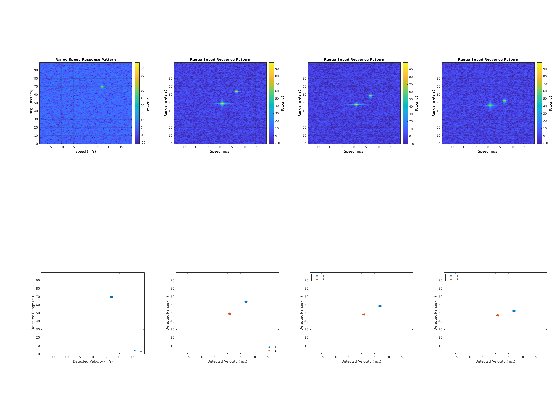

clf;
figure;
axis fill;
tiledlayout(2,4,TileSpacing="none",Padding="tight")
for i = 0:3
    %subplot of the Doppler in the left column
    nexttile
    [X,map] = frame2im(F_rngdop(ceil(1 + (i/4)*frames_to_compute)));
    imshow(X,map)
end
for i = 0:3
    %subplot of the clustering in the right column
    nexttile
    [X,map] = frame2im(F_clusters(ceil(1 + (i/4)*frames_to_compute)));
    imshow(X,map)
end

## Evaluating CFAR Performance

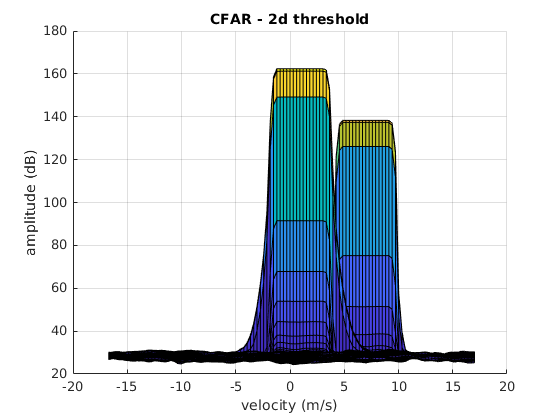

clf;
figure;
frame_to_evaluate = 50;

%evaluate the 2d CFAR detections for the desired frame
frame_resp = rng_dopp_responses(:,:,frame_to_evaluate);
CUT_indicies = simulator.Victim.Radar_Signal_Processor.CUT_indicies;

%configure the CFAR
release(simulator.Victim.Radar_Signal_Processor.CFARDetector2D);
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.ThresholdOutputPort = true;
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.OutputFormat ="CUT result";


%compute the CFAR
[detections,th] = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(frame_resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);

%determine range indicies in threshold detector
ranges = rnggrid(CUT_indicies(1,:)); %y
velocities = dopgrid(CUT_indicies(2,:)); %x

dopgrid_th = linspace(min(velocities), max(velocities),max(CUT_indicies(2,:)) - min(CUT_indicies(2,:) - 1));
rnggrid_th = linspace(min(ranges), max(ranges),max(CUT_indicies(1,:)) - min(CUT_indicies(1,:) - 1));
[X,Y] = meshgrid(dopgrid_th, rnggrid_th);

%convert the thresholds to db
th = 20 * log10(th);

th_surface = griddata(velocities,ranges,th,X,Y);
surf(X, Y, th_surface);
view(0,0);
title("CFAR - 2d threshold");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

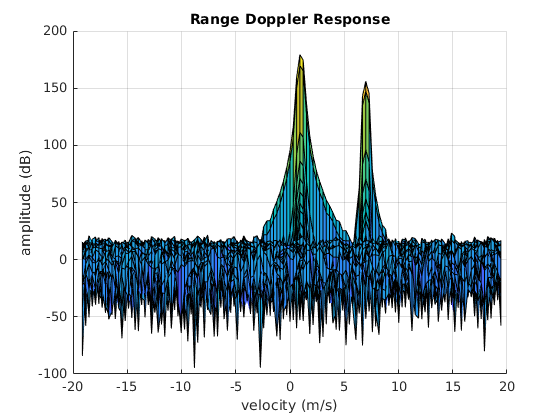


%convert the response to db
frame_resp = 20 * log10(abs(frame_resp).^2);
surf(dopgrid,rnggrid,frame_resp)
view(0,0);
title("Range Doppler Response");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

## Evaluating Range Performance

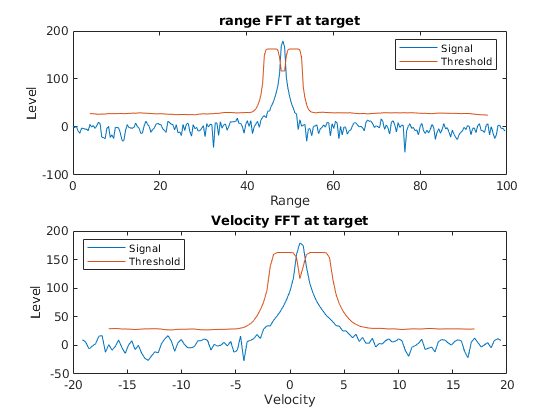

%find the maximum point
[M,I] = max(frame_resp,[],'all');
[rng_idx,vel_idx] = find(frame_resp == M);

%compute the indicies for the computed threshold
rng_idx_th = find(abs(rnggrid_th - rnggrid(rng_idx)) < 1e-4);
vel_idx_th = find(abs(dopgrid_th - dopgrid(vel_idx)) < 1e-4);

%plot range
rng_fft = frame_resp(:,vel_idx);
rng_th = th_surface(:,vel_idx_th);

subplot(2,1,1) 
plot(rnggrid,rng_fft,rnggrid_th,rng_th)
legend('Signal','Threshold','Location','Northeast')
xlabel('Range')
ylabel('Level')
title("range FFT at target")
%plot velocity
dop_fft = frame_resp(rng_idx,:);
dop_th = th_surface(rng_idx_th,:);

subplot(2,1,2) 
plot(dopgrid,dop_fft,dopgrid_th,dop_th)
legend('Signal','Threshold','Location','northwest')
xlabel('Velocity')
ylabel('Level')
title("Velocity FFT at target")